# Calculation of distance between two skew lines

Consider two lines $\( l_1 = q_1 + \lambda_1 \omega_1 \)$ and $\( l_2 = q_2 + \lambda_2 \omega_2 \)$ as defined just below definition 2.3 on MLS p. 66, with $\( \|\omega_1\| = \|\omega_2\| = 1 \).$ We now wish to calculate the minimum distance \( d \) between the two lines, measured along the line normal to both lines, the direction of which is determined by the unit vector \( n \). It is known that $\( \hat{\omega}_1 \omega_2 = n \sin \alpha \) $(as in MLS figure 2.15, p. 67). For calculation purposes we determine \( n \) as: $\[ n = \frac{\hat{\omega}_1 \omega_2}{\|\hat{\omega}_1 \omega_2\|}$. 

Let \( q_{1n} \) and \( q_{2n} \) be the two points on lines 1 and 2, respectively, where \( d \) is measured, with corresponding values $( \lambda_{1n} \) $）and $\( \lambda_{2n} \)$, respectively. Therefore, $\[ q_{2n} = q_2 + \lambda_{2n} \omega_2 = q_{1n} + d n = q_1 + \lambda_{1n} \omega_1 + d n, \]$similarly to what MLS explains just below figure 2.15. These are really three equations in three unknowns. To clarify this, let the coordinates of \( q_1 \) and \( q_2 \) be $\( [q_{1x} \; q_{1y} \; q_{1z}]^T \) and \( [q_{2x} \; q_{2y} \; q_{2z}]^T \),$ respectively. Let the components of \( \omega_1 \) and \( \omega_2 \) be $\( [\omega_{1x} \; \omega_{1y} \; \omega_{1z}]^T \) and \( [\omega_{2x} \; \omega_{2y} \; \omega_{2z}]^T \), respectively. Let the components of \( n \) be \( [n_x \; n_y \; n_z]^T \). $

Then, the above equation can be written as three equations: 

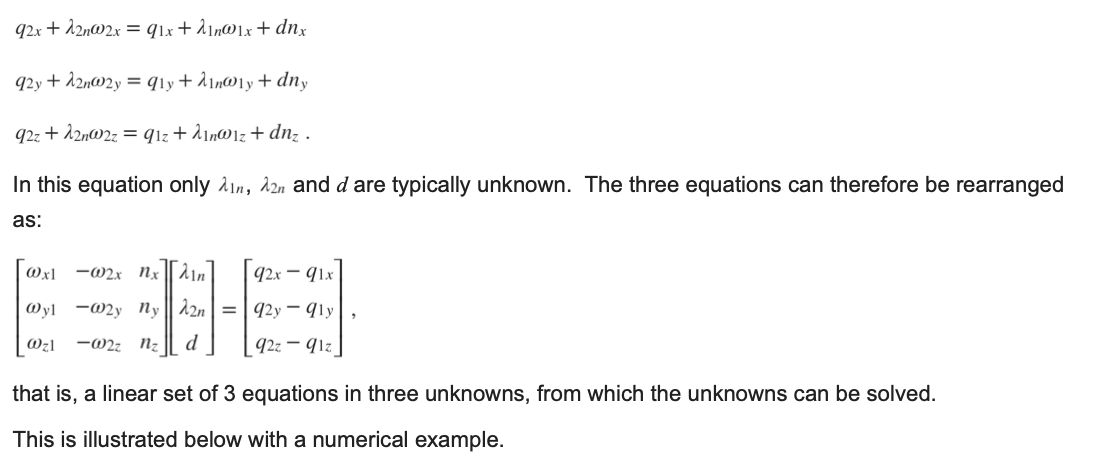

import robo.*
omega1 = [1,3,-2]'

omega1 =      1
     3
    -2


omega1 = omega1/norm(omega1)

omega1 =     0.2673
    0.8018
   -0.5345


omega2 = [4,2,-3]'

omega2 =      4
     2
    -3


omega2 = omega2/norm(omega2)

omega2 =     0.7428
    0.3714
   -0.5571



hatomega1 = hatm_sym(omega1)

hatomega1 =          0    0.5345    0.8018
   -0.5345         0   -0.2673
   -0.8018    0.2673         0


hatomega2 = hatm_sym(omega2)

hatomega2 =          0    0.5571    0.3714
   -0.5571         0   -0.7428
   -0.3714    0.7428         0


dum = hatomega1 * omega2 %这个就等于omega1 叉乘omega2 了

dum =    -0.2481
   -0.2481
   -0.4963


%这个n就是垂直于两条直线的公垂线的单位向量的方向

n = dum/norm(dum)

n =    -0.4082
   -0.4082
   -0.8165


%计算两个直线的夹角
alpha = atan2(dum'*n,omega1'*omega2);
rad2deg(alpha)

ans = 37.4328


%第一条直线上，距离第二条直线最近的点（公垂线在直线 1 上的端点）；
q1 = [3; 5; -2]

q1 =      3
     5
    -2


%第二条直线上，距离第一条直线最近的点（公垂线在直线 2 上的端点）
q2 = [6; -7; 4]

q2 =      6
    -7
     4


AA = [omega1, -omega2, n]

AA =     0.2673   -0.7428   -0.4082
    0.8018   -0.3714   -0.4082
   -0.5345    0.5571   -0.8165


bb = q2 - q1

bb =      3
   -12
     6



lambdas = AA\bb

lambdas =   -20.5791
  -10.7703
   -1.2247


lambda1n = lambdas(1)

lambda1n = -20.5791

lambda2n = lambdas(2)

lambda2n = -10.7703

d = lambdas(3)

d = -1.2247

q1n = q1 + lambda1n*omega1

q1n =    -2.5000
  -11.5000
    9.0000


q2n = q2 + lambda2n*omega2

q2n =     -2
   -11
    10



shouldbezero3times1 = q1n + n*d - q2n

shouldbezero3times1 =      0
     0
     0
